**1D Electric Potential of Line Charge: **

%xp = linspace(.1,1,100);
y = linspace(0.1,4,100) %distance from the line charge

y =     0.1000    0.1394    0.1788    0.2182    0.2576    0.2970    0.3364    0.3758    0.4152    0.4545    0.4939    0.5333    0.5727    0.6121    0.6515    0.6909    0.7303    0.7697    0.8091    0.8485    0.8879    0.9273    0.9667    1.0061    1.0455    1.0848    1.1242    1.1636    1.2030    1.2424    1.2818    1.3212    1.3606    1.4000    1.4394    1.4788    1.5182    1.5576    1.5970    1.6364    1.6758    1.7152    1.7545    1.7939    1.8333    1.8727    1.9121    1.9515    1.9909    2.0303


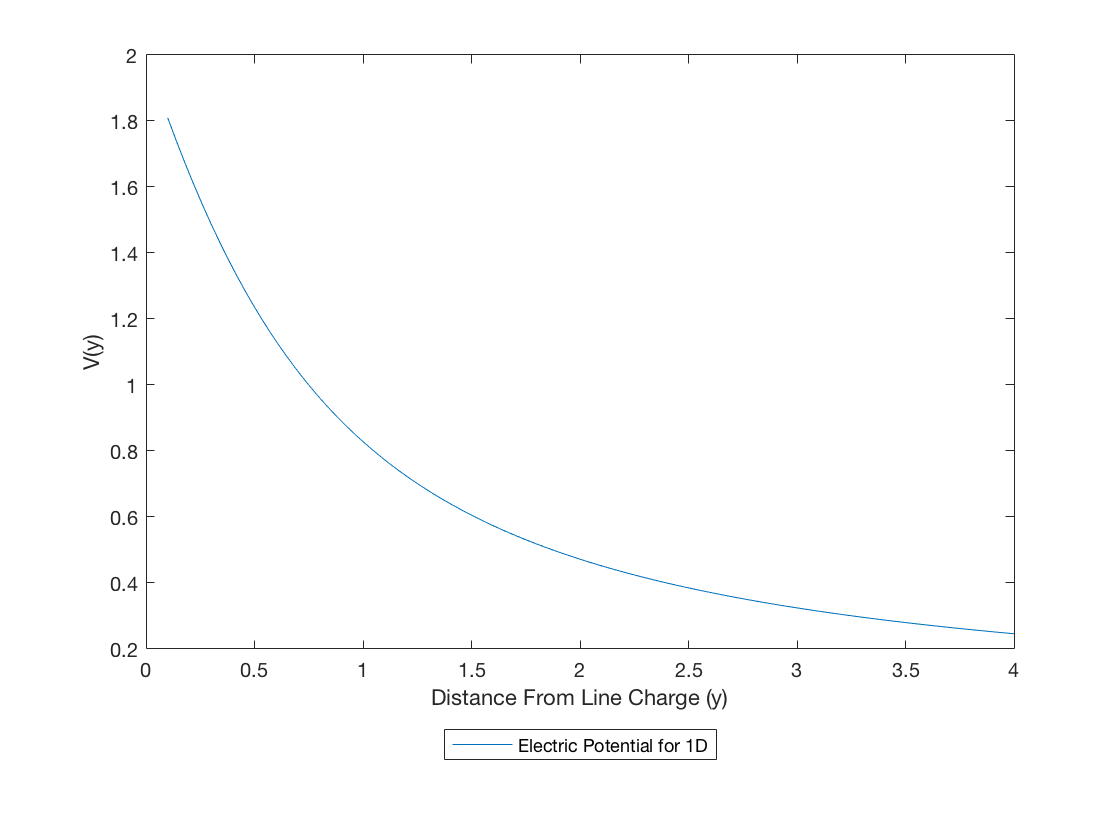

f=@(xp,y) ((2*xp)./sqrt(y.^2+xp.^2)); %In this case the electric potential
%fvector = np.vectorize(f) 
v = zeros(1,100); %empty list 
for i = 1:100
    variable = y(i);
    x =linspace(0,1,100); %setting up the limits
    f=integral (@(xp) ((2*xp)./sqrt(variable.^2+xp.^2)),0,1);
    %v.append(sci.romberg(f,0,1)) 
    v(i) = f;
end
plot (y,v)
legend('Electric Potential for 1D','Location','southoutside')
xlabel('Distance From Line Charge (y)')
ylabel('V(y)')

**1D Electric Field of Line Charge: **

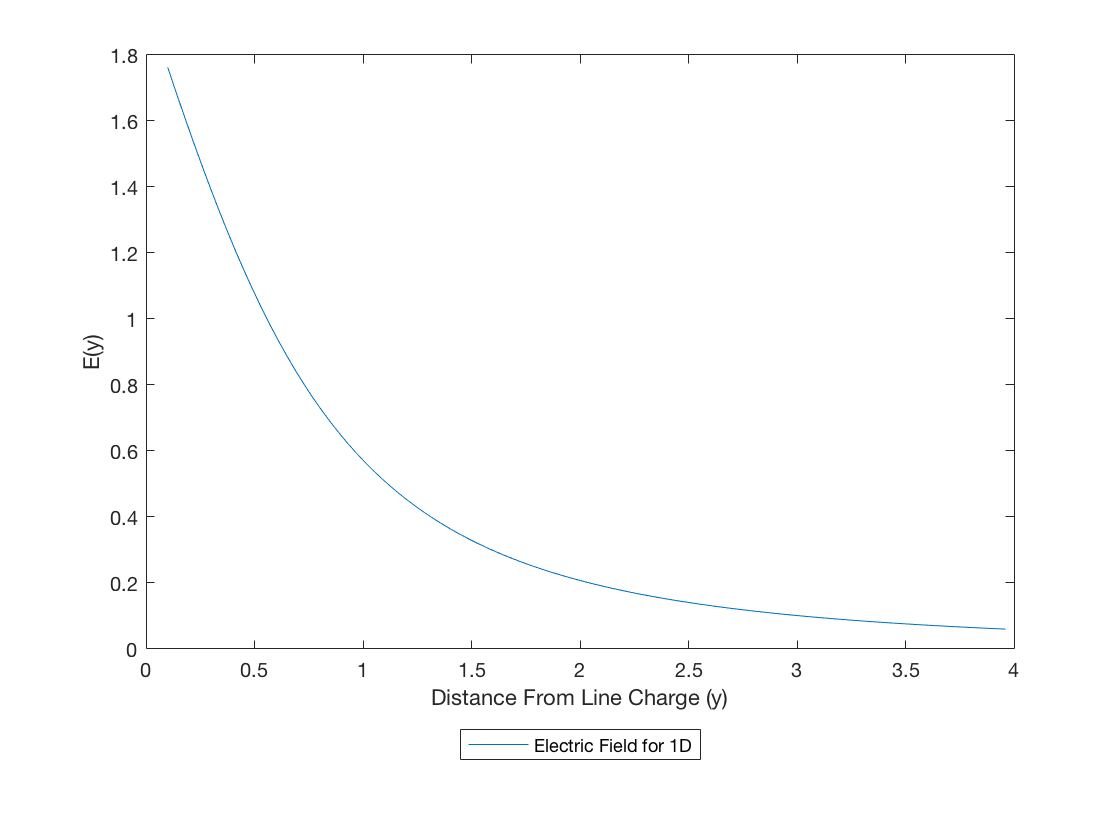

%E1D=(-1)*(diff(v)./diff(y)); %d/dx potenital the first derivative 
[Ey1D, Ex1D] = Der(-1*v,y);  %we can also use gradient
plot (Ex1D, Ey1D)
legend('Electric Field for 1D','Location','southoutside')
xlabel('Distance From Line Charge (y)')
ylabel('E(y)')

**2D Electric Potential of Line Charge: **

*L-shaped *line charge:

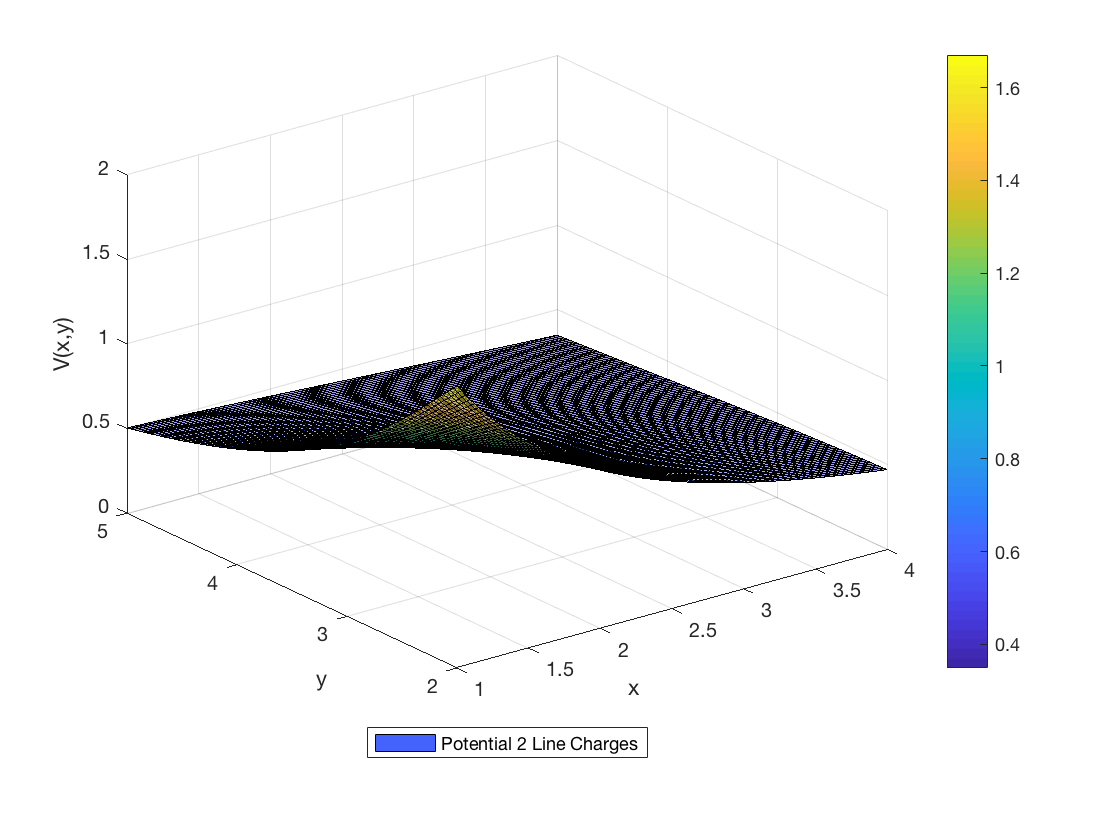

x1 = linspace(1,4,100);
y1= linspace(2,5,100);
xp1= linspace(0,1,100);
yp1 = linspace(1,2,100);
fx1 = @(x1,y1,xp1)(xp1.^2 ./sqrt((x1-xp1).^2 + (y1-1).^2));
fy1 = @(x1,y1,yp1)(yp1 ./sqrt(x1.^2 + (y1-yp1).^2));

%V2D = [];
V2D = zeros(100,100); %or zeros(length(x1),length(y1))

for i=1:100
    for j=1:100
         vx1=trapz(xp1,fx1(x1(i),y1(j),xp1)) ; 
        vy1=trapz(yp1,fy1(x1(i),y1(j),yp1)) ; 
        V2D(j,i)=vx1+vy1;
   
    end
end
% mesh(x1,y1,V2D)
% xlabel('x')
% ylabel('y')

surf(x1,y1,V2D,'FaceAlpha',0.5)
legend('Potential 2 Line Charges','Location','southoutside')
xlabel('x');
ylabel('y');
zlabel('V(x,y)')
colorbar

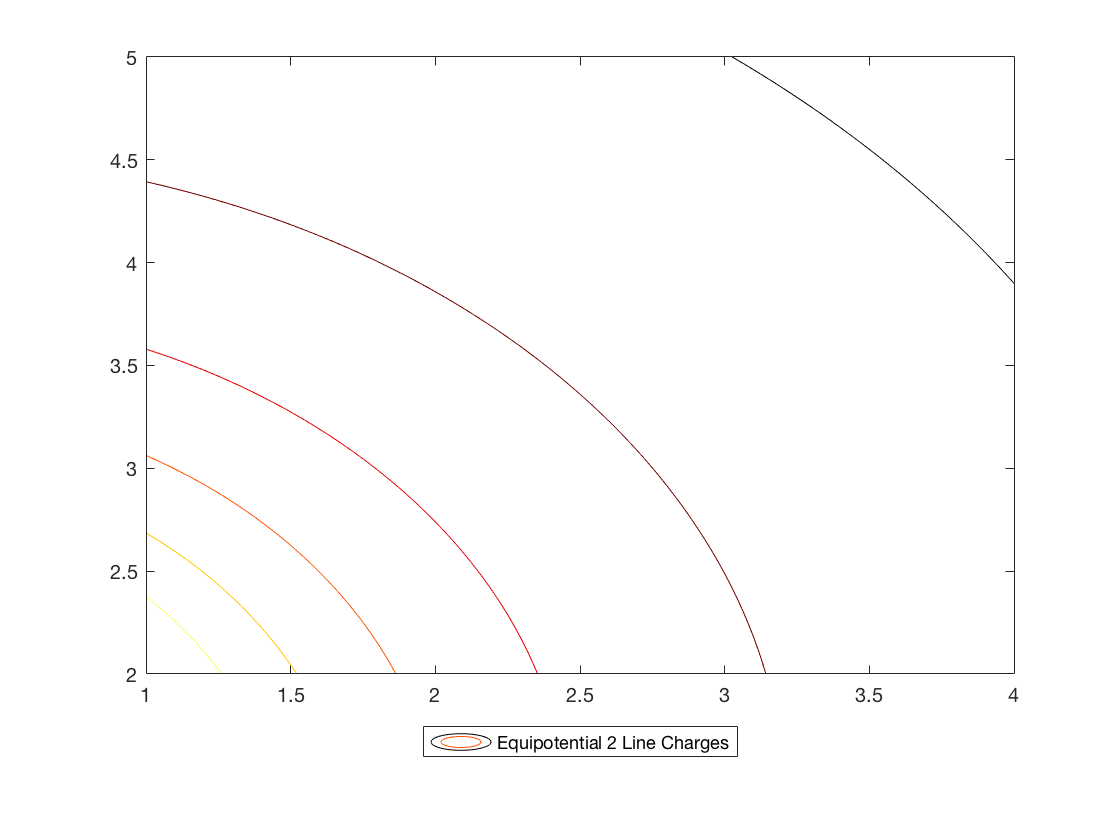

%%%
%EquiPotential contor and Electric field :
contour(x1,y1,V2D)
colormap(hot)
legend('Equipotential 2 Line Charges','Location','southoutside')

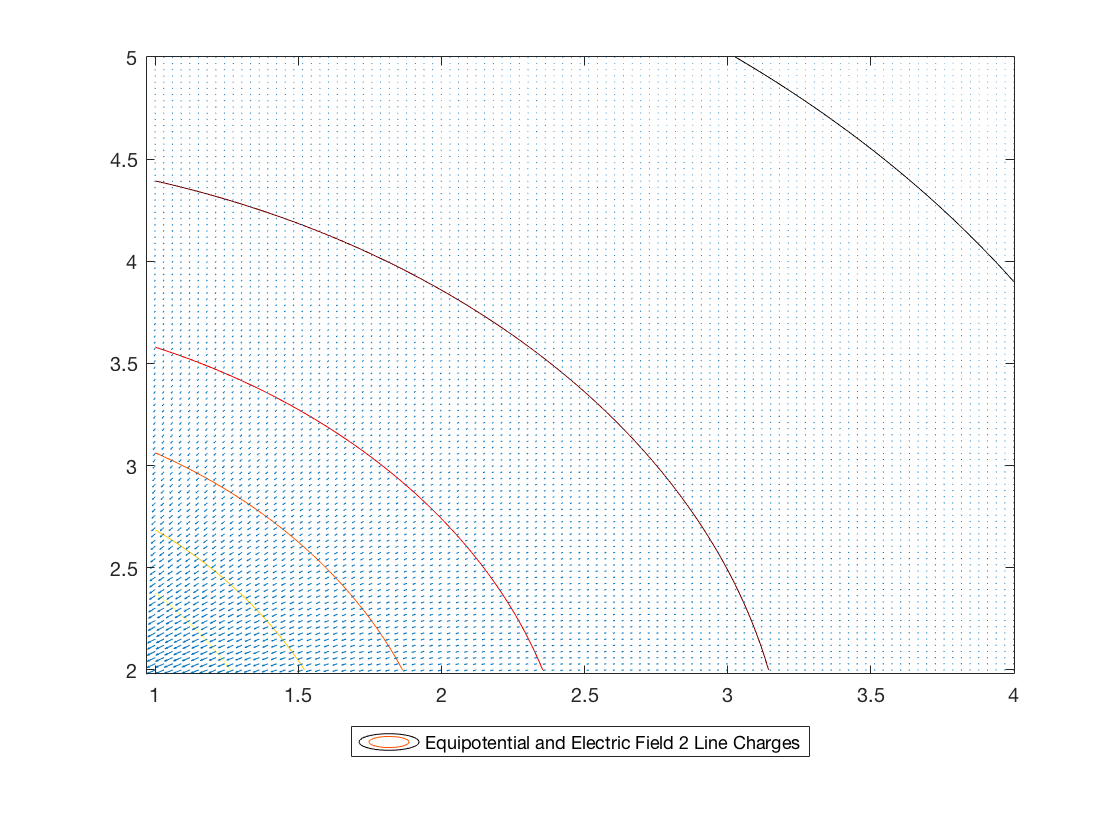

% In this case the "altitude" is electric.
% Equipotential lines are always perpendicular to the electric field.
%so the arrows (vectors) are the electric field or gradient 

[X2,Y2] = meshgrid(x1,y1);
[DX2,DY2] = gradient(V2D); %we can use gradient 
contour(x1,y1,V2D)
colormap(hot)
hold on
quiver(X2,Y2,DX2,DY2)
hold off
legend('Equipotential and Electric Field 2 Line Charges','Location','southoutside')

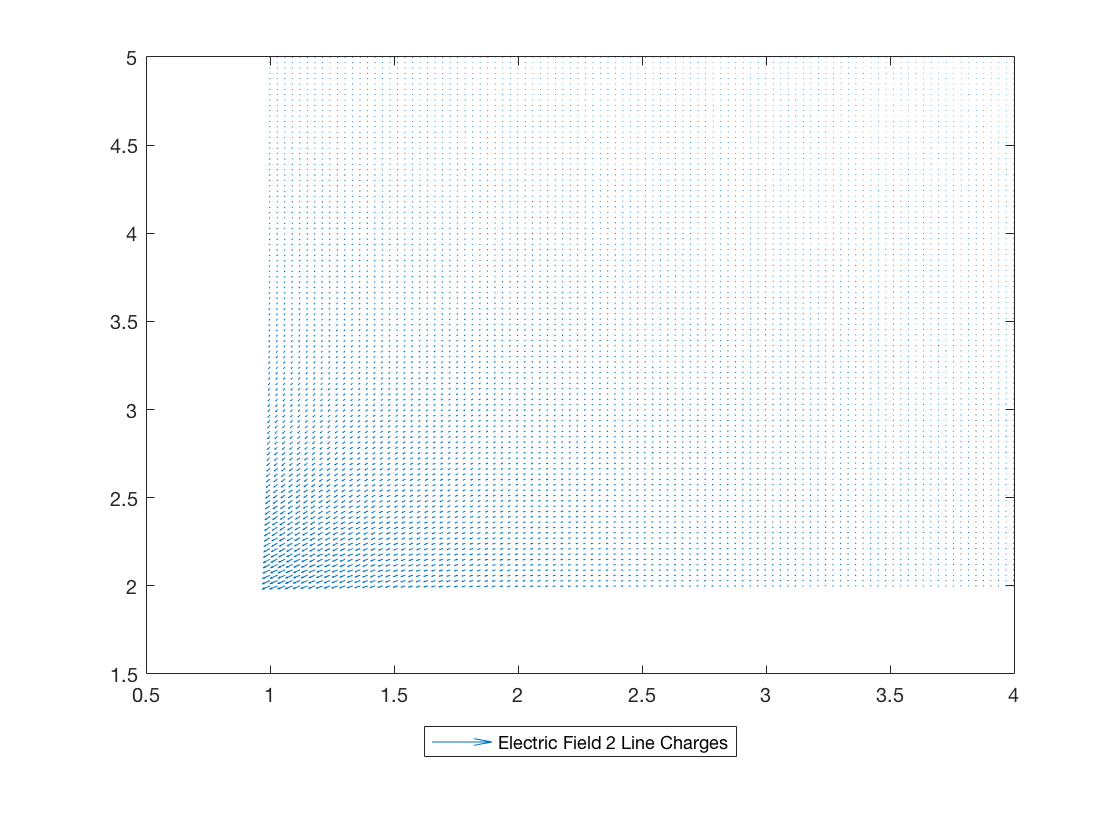

%%%       


quiver(X2,Y2,DX2,DY2)
legend('Electric Field 2 Line Charges','Location','southoutside')

**2D Disk of Charge: **

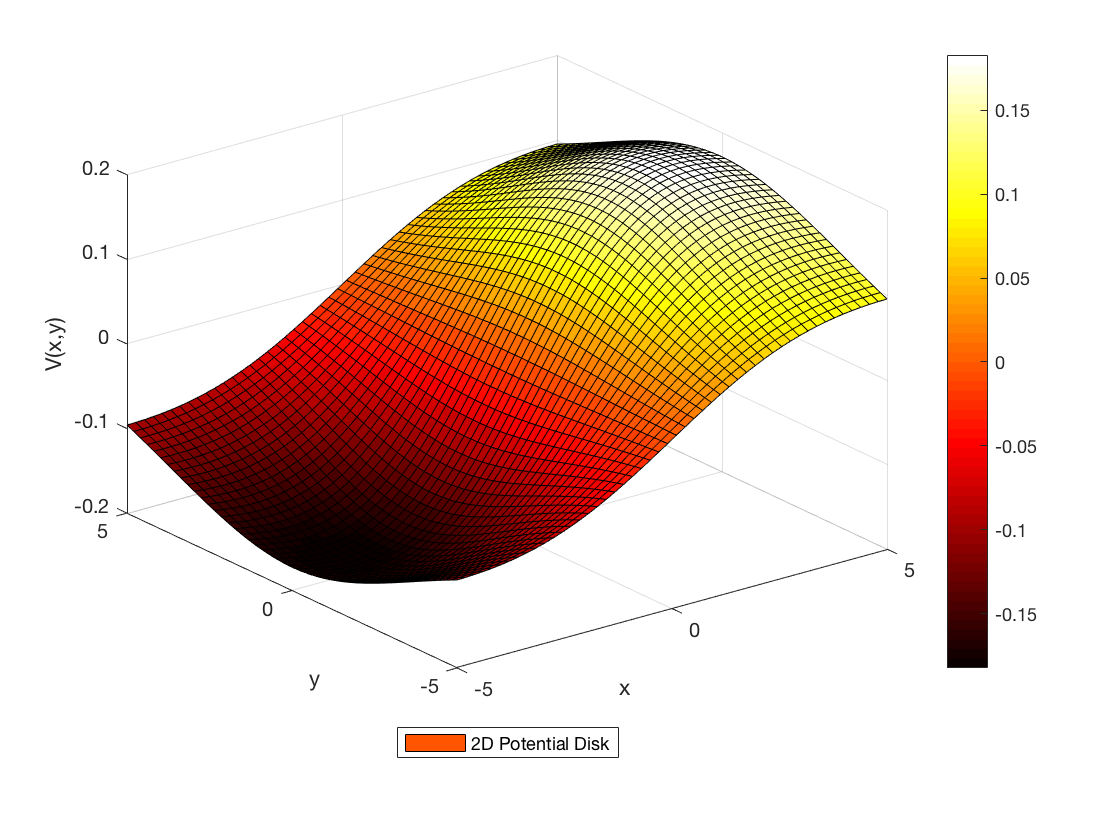

x3 = linspace(-5,5,50);
y3 = linspace(-5,5,50);

f3 = @(r,t,x3,y3) cos(t).*(r.^2)./sqrt((x3-r.*cos(t)).^2 + (y3-r.*sin(t)).^2 + 5.^2); %define at a distance z=5 from the disk
%(.) multiplication for the cos cause we want an element by element multipilcation 
% since there's an array of t and an array of r
VDisk = zeros(50,50);

for i=1:50
    for j=1:50
        dx3=x3(i);
        dy3=y3(j);
        r=linspace(0,2,50); %integral dr from 0 to 2
        t=linspace(0,2*pi,50); %integral dt from 0 to 2pi
        vdisk=integral2(@(r,t)f3(r,t,dy3,dx3),0,2,0,2*pi); %integral2: evaluate double integral
        VDisk(i,j)=vdisk;
    end
end

surf(x3,y3,VDisk)
legend('2D Potential Disk','Location','southoutside')

xlabel('x');
ylabel('y');
zlabel('V(x,y)')
colorbar

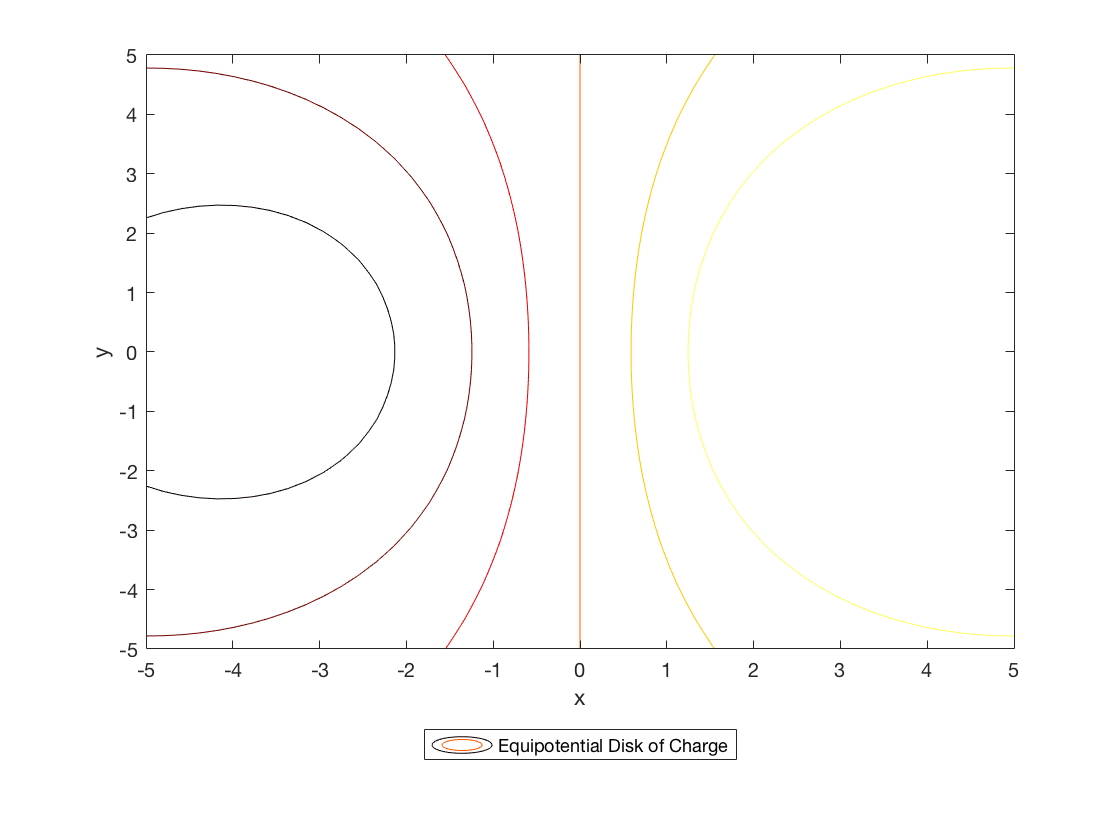


%Electric field:

[X3,Y3] = meshgrid(x3,y3);
[DX3,DY3] = gradient(VDisk);

figure
contour(x3,y3,VDisk)
colormap(hot)
legend('Equipotential Disk of Charge','Location','southoutside')
xlabel('x');
ylabel('y');

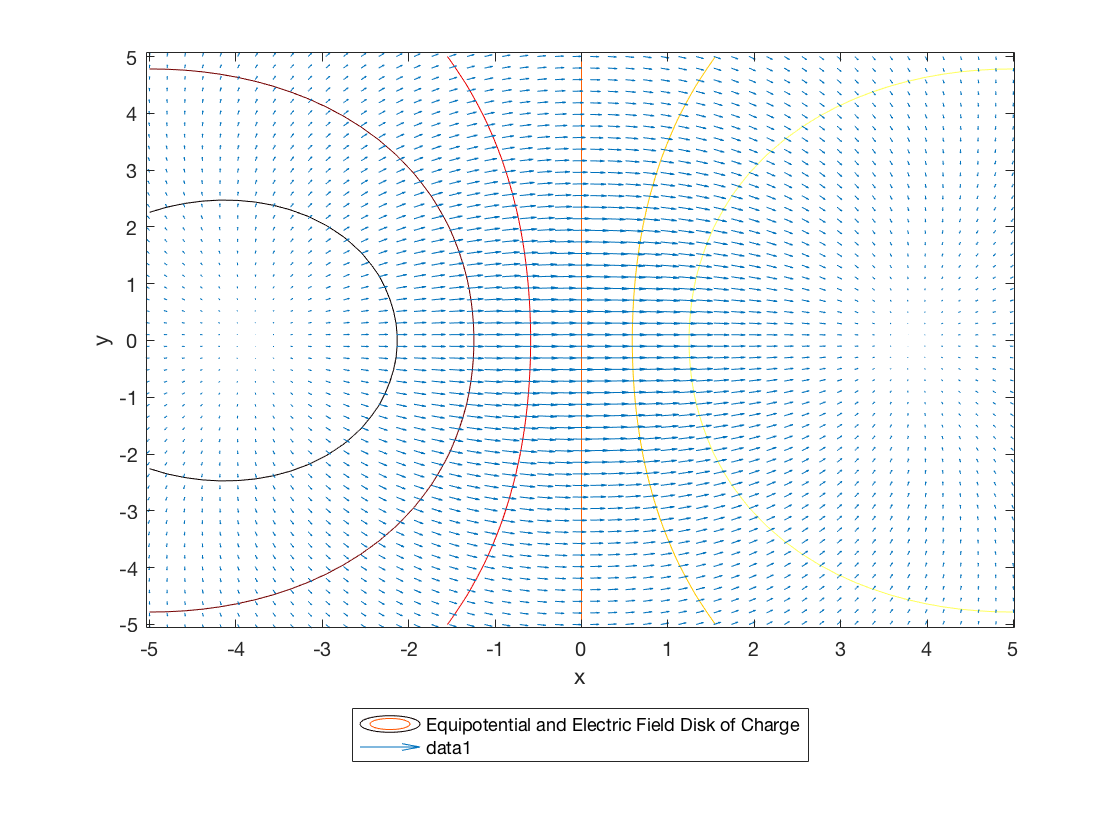


[X3,Y3] = meshgrid(x3,y3);
[DX3,DY3] = gradient(VDisk);
contour(x3,y3,VDisk)
colormap(hot)
legend('Equipotential and Electric Field Disk of Charge','Location','southoutside')
xlabel('x');
ylabel('y');

hold on
quiver(X3,Y3,DX3,DY3)
hold off